Welcome to the Q-Bat use case, in which we will simulate the thermal behaviour of the generic battery pack during a fire test.

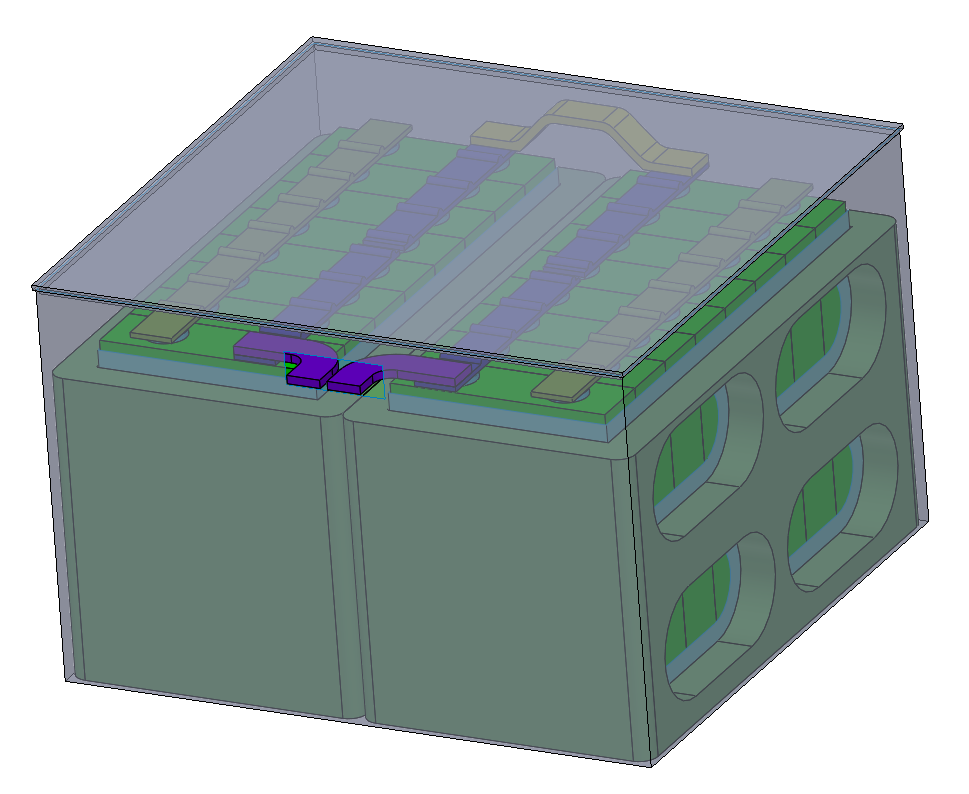

Our model imitates a generic battery pack and consists of 16 prismatic cells, casing, connectors, bus bars and cell holders. We have prepared the model as shown in the picture above.

Let's start with clearing your workspace and loading the battery model.

clc
clear
close all

model = loadModel('fire_test_model.mat');

You can display model parts by reference to their component name using the following command:

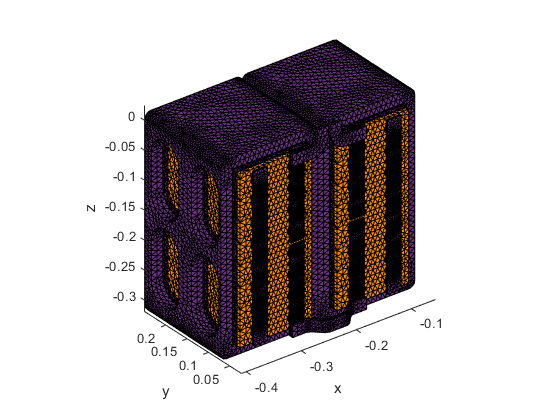

cells_pack = ["cell_.*","connector_.*","casing_inner.*", "holder.*", "bus_bar.*"];

cells = ["cell_.*","connector_.*"];

model.displayComponents(cells_pack);

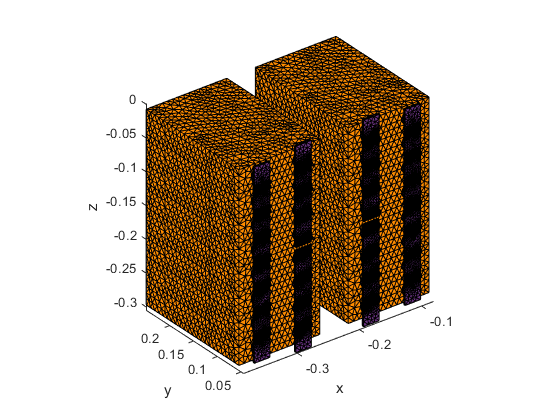

model.displayComponents(cells);

The model has been prepared with our GUI pre-processor. You can access it by the following command. All of the model preparation steps such as detecting contacts, creating electrical circuits and applying boundary conditions can be easily done using our GUI wizard, however, for your convenience, we have prepared it in the form of a ready-to-go script.

% w = wizard.WizardGUI();

Fire test consists of 3 phases:

- 70 s of direct contact with a fire source

- 60 s of indirect contact with a fire source

- up to 3 hours of cooling to the ambient temperature

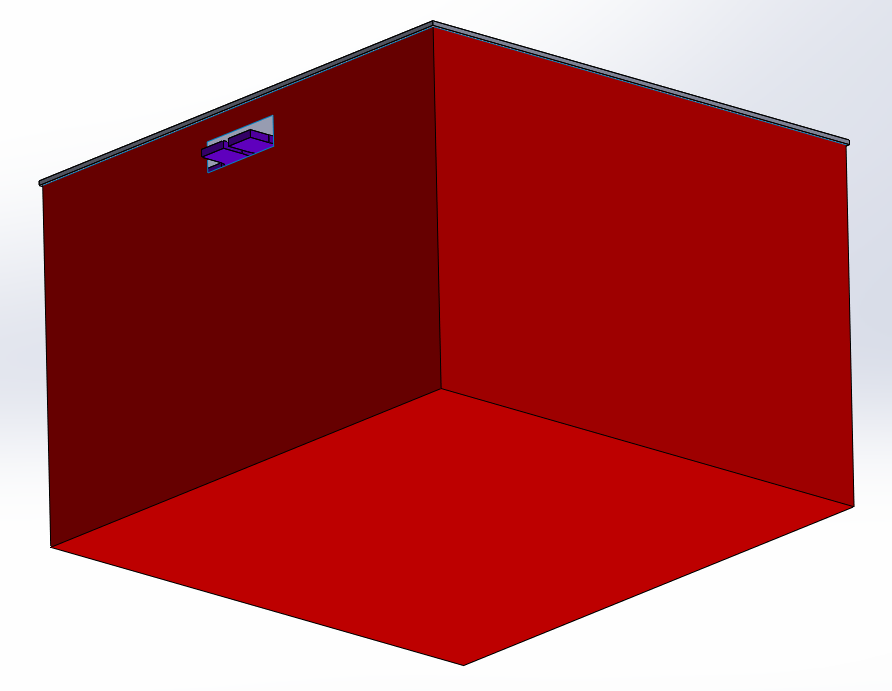

Heating due to contact with a flame is simulated as convective boundary condition applied to casing outside surfaces, as marked in the picture above. Ambient temperature for convective boundary condition is changing in time to model different phases of the test, as shown in the plot below:

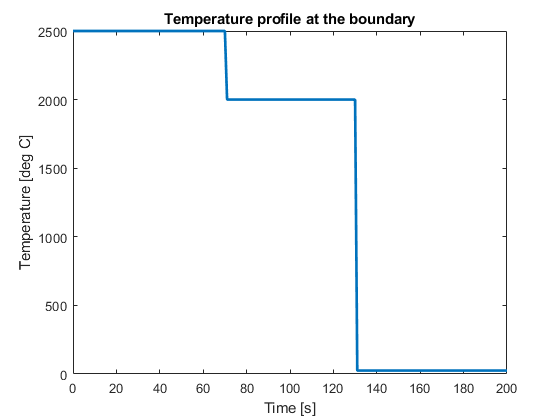

plot([0,70,71,130,131,200],[2500,2500,2000,2000,25,25], 'LineWidth',2);
title('Temperature profile at the boundary')
xlabel('Time [s]')
ylabel('Temperature [deg C]')

A constant current of 5 A will be applied during the whole duration of the test. Initial cells' state of charge will be set to 60 %. The initial temperature of 25 deg. C has been chosen for all components.

current_profile = table([0; 12800], [60; 60]);
current_profile.Properties.VariableNames = {'t','current'};

model.setCurrentProfile('ele_circ', current_profile);

model.setIC(".*", 'T', 25);

model.setIC("cell_.*", 'T', 25, 'SOC', 0.6);

Now it is time to prepare our model for simulation. Q-Bat is based on the Reduced Order Modeling approach and requires an additional step of model assemblation and reduction but allows to perform simulation substantially faster. If you have access to MATLAB's parallel toolbox you can uncomment the first line of code and additionally decrease simulation time by allowing parallel computing.

%model.flag_is_parallel = true;
tic;
model_struct = model.prepare();

Elapsed linear fem grid assemblation time: 0.30129s.
Elapsed linear fem grid assemblation time: 0.88575s.
Elapsed linear fem grid assemblation time: 0.027956s.
Elapsed linear fem grid assemblation time: 0.50575s.
Elapsed linear fem grid assemblation time: 0.010893s.
Elapsed linear fem grid assemblation time: 0.3803s.
Elapsed linear fem grid assemblation time: 0.23265s.
Elapsed linear fem grid assemblation time: 0.0093319s.
Elapsed electro grid assemblation time: 0.10466s.
Assembling fem body: casing_top_1_1, number: 1/63
Elapsed body assemblation time: 0.048074s.
Assembling fem body: casing_outer1_1, number: 2/63
Elapsed body assemblation time: 0.15903s.
Assembling fem body: holder_1, number: 3/63
Elapsed body assemblation time: 0.0012047s.
Assembling fem body: holder_2, number: 4/63
Elapsed body assemblation time: 3.66e-05s.
Assembling fem body: bus_bar1_1_1, number: 5/63
Elapsed body assemblation time: 2.07e-05s.
Assembling fem body: casing_inner_1, number: 6/63
Elapsed body assembla

model_prepare_time = toc;
fprintf("Model preparation took %4.1f seconds.", model_prepare_time)

Model preparation took 615.4 seconds.

You can save the already prepared model to re-use it later with a different current profile, ambient temperature etc.

% save('model_struct.mat','model_struct');
% model.saveModel('model_preped.mat');

Finally, we can run our model. We will simulate 130 s of battery pack operation during the 1st and 2nd phase of the fire test when we have direct/indirect contact with the flame. A time step of 1 s has been chosen to obtain detailed results in the critical test phases.

tic;

model.run(1, 130, 'maxSubIter', 20, 'electroSubsteps', 20, 'solver', 'Direct', ...
    'signals_data', model_struct);

Time step: 1, real time: 1.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:32
Time step: 2, real time: 2.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:34
Time step: 3, real time: 3.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:36
Time step: 4, real time: 4.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:38
Time step: 5, real time: 5.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:40
Time step: 6, real time: 6.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:42
Time step: 7, real time: 7.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:04:44
Time step: 8, real time: 8.000, no. subiters: 2, maxTempeatureRes: 0.

model_run_time = toc;
fprintf("Simulation run took %4.1f seconds.", model_run_time)

Simulation run took 269.0 seconds.

We can track temperature change of components as trend plots or 3D temperature fields.

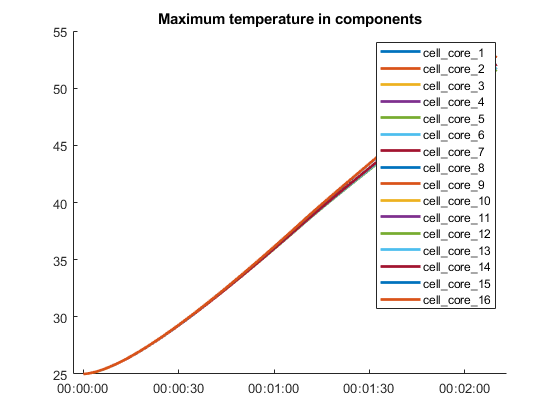

model.plotMaxTempOverTime("cell_cores")

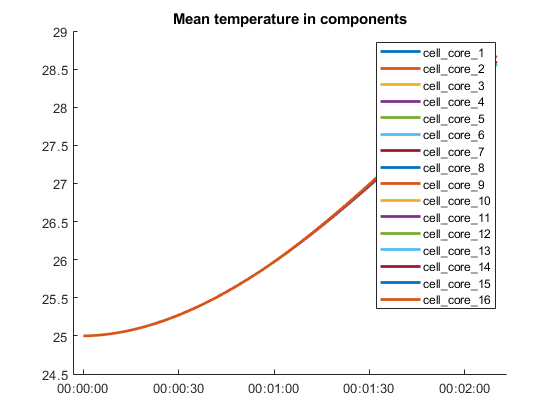

model.plotMeanTempOverTime("cell_cores")

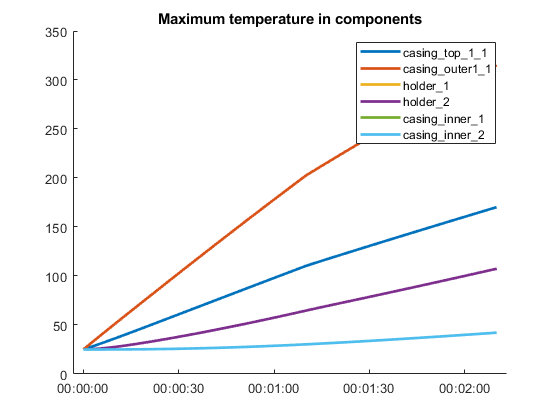

model.plotMaxTempOverTime("casings_together")

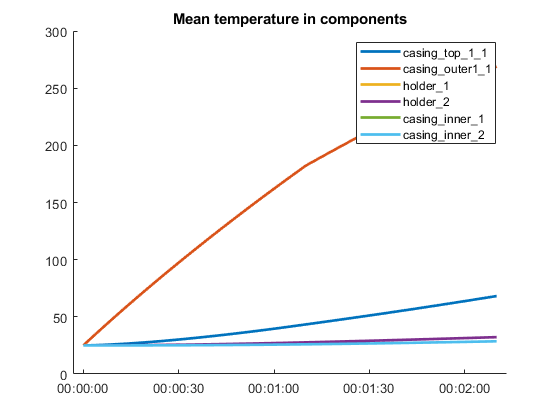

model.plotMeanTempOverTime("casings_together")

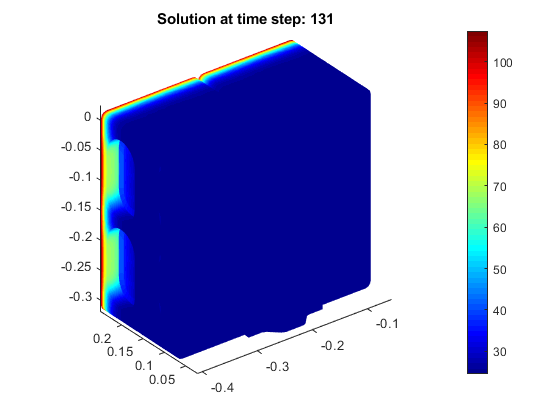

model.plotSolution(cells_pack)

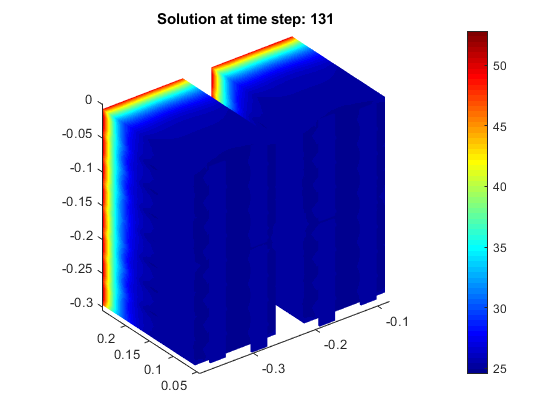

model.plotSolution(cells)

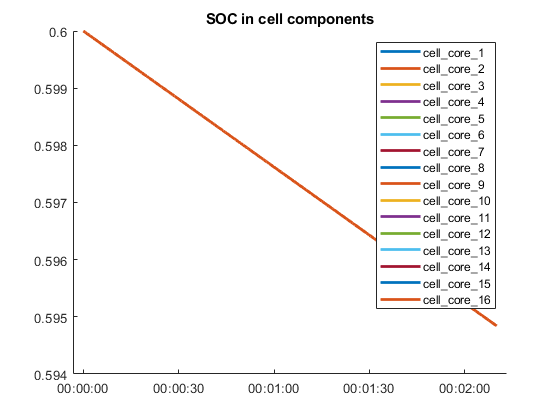

model.plotSOCOverTime()

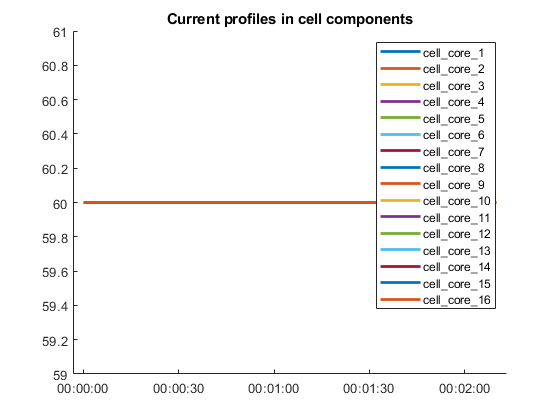

model.plotCurrentOverTime()

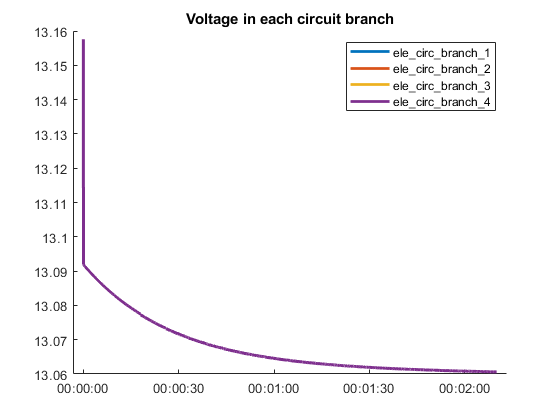

model.plotCircuitVoltage()

Full 3D temperature profile can be exported to CGNS file to be examined in other post-processing software such as Paraview.

% model.exportSolutionToCGNS(".*", 'fire_test.cgns', 200);

The next step of the fire test is to remove the battery pack from the heating source and monitor its cooling to the ambient temperature for up to 3 hours. For that part, we will adjust the time step from 1 s to 100 s because components will cool slowly and such a high resolution is not needed.

tic;

model.run(100, 120, 'maxSubIter', 20, 'electroSubsteps', 20, 'solver', 'Direct', ...
    'signals_data', model_struct, 'startStep', 131);

Time step: 131, real time: 230.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:08
Time step: 132, real time: 330.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:10
Time step: 133, real time: 430.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:12
Time step: 134, real time: 530.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:14
Time step: 135, real time: 630.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:17
Time step: 136, real time: 730.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:19
Time step: 137, real time: 830.000, no. subiters: 2, maxTempeatureRes: 0.000000, maxMassFlowRes: 0.000000, at time: 30-May-2022 09:09:21
Time step: 138, real time: 930.000, no. s

model_run_time2 = toc;
fprintf("Simulation run took %4.1f seconds.", model_run_time2)

Simulation run took 258.9 seconds.

Let's check cells and casings temperature profile throughout the test and the 3D temperature field at the end.

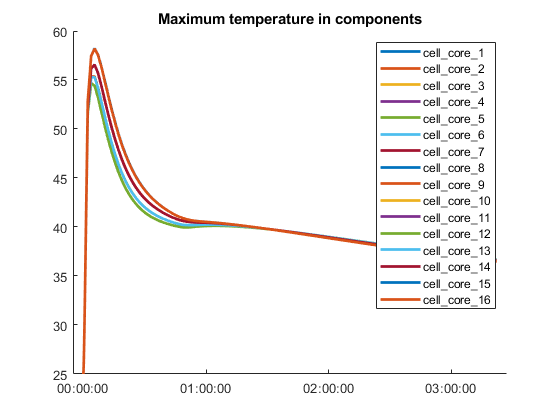

model.plotMaxTempOverTime("cell_cores")

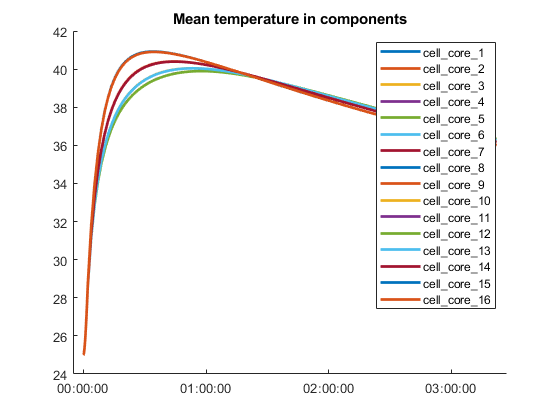

model.plotMeanTempOverTime("cell_cores")

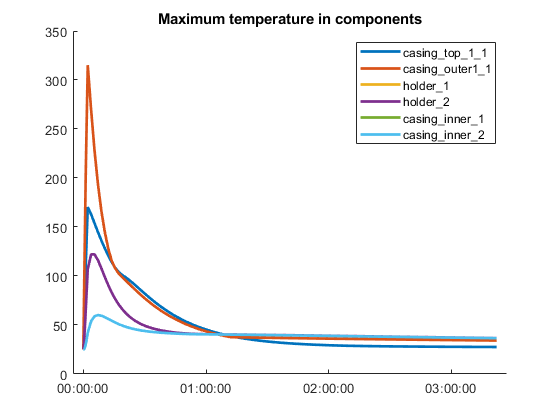

model.plotMaxTempOverTime("casings_together")

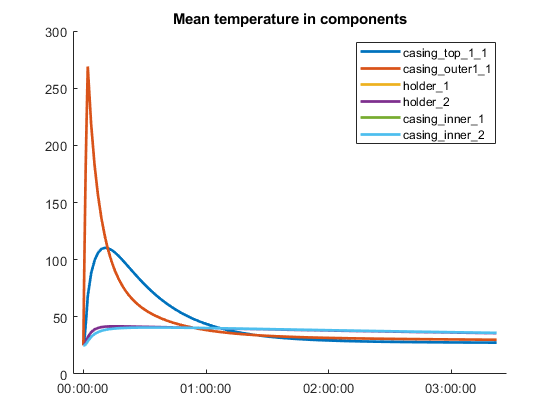

model.plotMeanTempOverTime("casings_together")

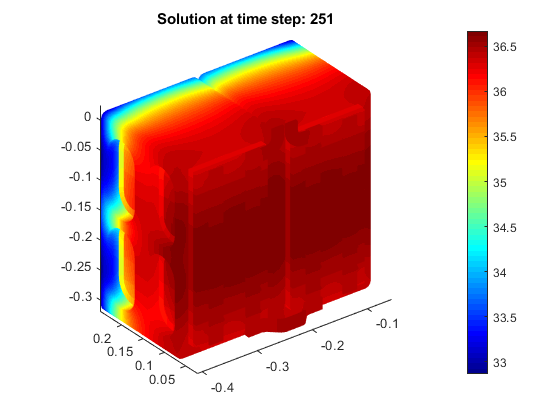

model.plotSolution(cells_pack)

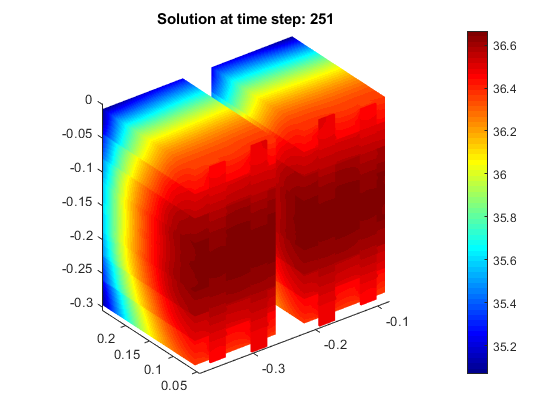

model.plotSolution(cells)